# How to import data from Datastream Web Services using MATLAB

Copyright (c) 2018, MathWorks, Inc.

This demo shows how to retrieve historical data from Datastream Web Services, including:

- How to import data for one securitiy and one datatype

- How to import data in different time frequencies

- How to import data with multiple datatypes

- How to import data with multiple securities and datatypes

System requirements

- [MATLAB® R2018b](https://www.mathworks.com/products/matlab.html)

- [Datafeed Toolbox™](https://www.mathworks.com/products/datafeed.html)

- [Financial Toolbox™](https://www.mathworks.com/products/finance.html)

Data request limits

- Maximum instruments per time series or snapshot request: 50 

- Maximum datatypes per time series or snapshot request: 50 

- Maximum instruments x datatypes cannot exceed 100 

This is the MATLAB code used in the video demo of the same title. You can find the video in the link below:

[https://www.mathworks.com/videos/how-to-import-data-from-datastream-web-services-using-matlab-1537437053263.html](https://www.mathworks.com/videos/how-to-import-data-from-datastream-web-services-using-matlab-1537437053263.html) 

## **Establish connection to Datastream Web Services**

clear;
c = datastreamws('username','password'); % You need to obtain credentials from Datastream

## **Retrieve historical data **

**Specify symbol and datatype**

You can find the information (e.g., symbol and datatype cides) at Datastream Navigator 

[http://product.datastream.com/browse/Search.aspx](http://product.datastream.com/browse/Search.aspx)

symbol = '@AAPL';
dataType = 'P';

**Retrieve end-of-day historical data**

Syntax: history(connection, symbol, dataType, startDate, endDate)

data1 = history(c,symbol, dataType, today-365, today-1)

data1 = 261×1 timetable
            Time              P   
    ____________________    ______

    13-Nov-2017 00:00:00    173.97
    14-Nov-2017 00:00:00    171.34
    15-Nov-2017 00:00:00    169.08
    16-Nov-2017 00:00:00     171.1
    17-Nov-2017 00:00:00    170.15
    20-Nov-2017 00:00:00    169.98
    21-Nov-2017 00:00:00    173.14
    22-Nov-2017 00:00:00    174.96
    23-Nov-2017 00:00:00    174.96
    24-Nov-2017 00:00:00    174.97
    27-Nov-2017 00:00:00    174.09
    28-Nov-2017 00:00:00    173.07
    29-Nov-2017 00:00:00    169.48
    30-Nov-2017 00:00:00    171.85
    01-Dec-2017 00:00:00    171.05
    04-Dec-2017 00:00:00     169.8


**Retrieve historical data in different time frequencies**

You can retrieve data by specifying time frequencies, such as:

- D = Daily (Default)

- W = Weekly

- M = Monthly

- Q = Quarterly

- Y = Yearly

data2_M = history(c,symbol, dataType, 'Jan-31-2018', 'Apr-30-2018','M')

data2_M = 4×1 timetable
            Time              P   
    ____________________    ______

    31-Jan-2018 00:00:00    167.43
    28-Feb-2018 00:00:00    178.12
    30-Mar-2018 00:00:00    167.78
    30-Apr-2018 00:00:00    165.26


data2_Q = history(c,symbol, dataType, 'Mar-31-2017', 'Dec-31-2017','Q')

data2_Q = 4×1 timetable
            Time              P   
    ____________________    ______

    31-Mar-2017 00:00:00    143.66
    30-Jun-2017 00:00:00    144.02
    29-Sep-2017 00:00:00    154.12
    29-Dec-2017 00:00:00    169.23


data2_Y = history(c,symbol, dataType, 'Dec-31-2014', 'Dec-31-2017','Y')

data2_Y = 4×1 timetable
            Time              P   
    ____________________    ______

    31-Dec-2014 00:00:00    110.38
    31-Dec-2015 00:00:00    105.26
    30-Dec-2016 00:00:00    115.82
    29-Dec-2017 00:00:00    169.23


**Retrieve historical data with multiple datatypes**

In this section, we will use the following datatypes:

- PO = open price

- PH = intraday high price 

- PL = intraday low price

- UP = unadjusted close price

symbol = {'@AAPL'};
dataType = {'PO', 'PH', 'PL', 'UP'};
data3_raw = history(c,symbol, dataType, 'Dec-20-2017', 'May-20-2018')

data3_raw = 108×4 timetable
            Time              PO        PH        PL        UP  
    ____________________    ______    ______    ______    ______

    20-Dec-2017 00:00:00    174.87    175.42    173.25    174.35
    21-Dec-2017 00:00:00    174.17    176.02     174.1    175.01
    22-Dec-2017 00:00:00    174.68    175.42     174.5    175.01
    25-Dec-2017 00:00:00       NaN       NaN       NaN    175.01
    26-Dec-2017 00:00:00     170.8    171.47    169.68    170.57
    27-Dec-2017 00:00:00     170.1    170.78    169.71     170.6
    28-Dec-2017 00:00:00       171    171.85    170.48    171.08
    29-Dec-2017 00:00:00    170.52    170.59    169.22    169.23
    01-

Remove missing data

data3_clean = rmmissing(data3_raw)

data3_clean = 103×4 timetable
            Time              PO        PH        PL        UP  
    ____________________    ______    ______    ______    ______

    20-Dec-2017 00:00:00    174.87    175.42    173.25    174.35
    21-Dec-2017 00:00:00    174.17    176.02     174.1    175.01
    22-Dec-2017 00:00:00    174.68    175.42     174.5    175.01
    26-Dec-2017 00:00:00     170.8    171.47    169.68    170.57
    27-Dec-2017 00:00:00     170.1    170.78    169.71     170.6
    28-Dec-2017 00:00:00       171    171.85    170.48    171.08
    29-Dec-2017 00:00:00    170.52    170.59    169.22    169.23
    02-Jan-2018 00:00:00    170.16     172.3    169.26    172.26
    0

Plot candlestick chart

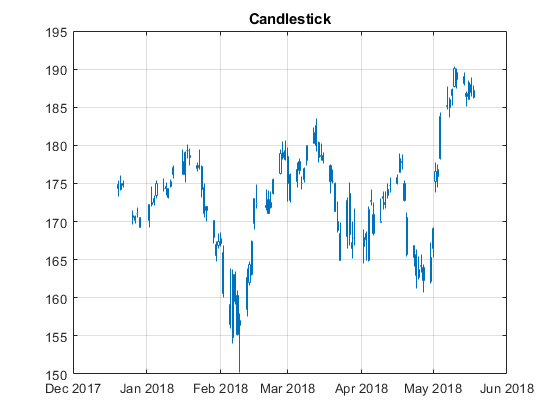

data3_clean.Properties.VariableNames = {'Open' , 'High', 'Low', 'Close'};
candle(data3_clean)
title('Candlestick')

Calculate and plot Bollinger bands

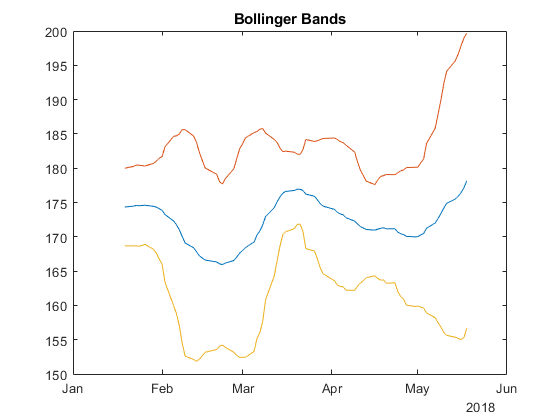

[middle,upper,lower]= bollinger(data3_clean(:,'Close'));
CloseBollinger = [middle.Close, upper.Close,lower.Close];
plot(middle.Time,CloseBollinger)
title('Bollinger Bands')

**Retrieve historical data with multiple securities and datatypes**

Multiple symbols and multiple datatypes

symbol = {'@AAPL','U:BAC'}

symbol = 1×2 cell array
    {'@AAPL'}    {'U:BAC'}


dataType = {'P','DY'}

dataType = 1×2 cell array
    {'P'}    {'DY'}


data4 = history(c,symbol, dataType, today-10, today-1);
AAPL = data4.x_AAPL

AAPL = 6×2 timetable
            Time              P        DY 
    ____________________    ______    ____

    05-Nov-2018 00:00:00    201.59    1.45
    06-Nov-2018 00:00:00    203.77    1.43
    07-Nov-2018 00:00:00    209.95    1.39
    08-Nov-2018 00:00:00    208.49     1.4
    09-Nov-2018 00:00:00    204.47    1.43
    12-Nov-2018 00:00:00    194.17     1.5


BAC = data4.U_BAC

BAC = 6×2 timetable
            Time              P       DY 
    ____________________    _____    ____

    05-Nov-2018 00:00:00    28.06    2.14
    06-Nov-2018 00:00:00    28.21    2.13
    07-Nov-2018 00:00:00    28.54     2.1
    08-Nov-2018 00:00:00    28.87    2.08
    09-Nov-2018 00:00:00    28.52     2.1
    12-Nov-2018 00:00:00    27.75    2.16
